Using pre-defined BS
Starting MRO with downtilt=5
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
Reseting tx antenna arrays...

[Generate layout]	Setting tx positions...	Setting rx positions...done.
	Setting tx antenna arrays...1(of 3)/2(of 3)/3(of 3)/done.
	Setting layout scenarios for all users...done.
Saving layout file...success.
Layout: 3GPP_38.901_UMa
Starting channel generation using QuaDRiGa v2.4.0-0
3 receivers, 3 transmitters, 2 frequencies (2.0 GHz, 28.0 GHz)


Generating channel builder objects - 6 builders, 18 channel segments
Initializing random generators
Generating parameters
Parameters   [oooooooooooooooooooooooooooooooooooooooooooooooooo]     1 seconds
Preparing multi-frequency simulations - 12 builders
Channels     [oooooooooooooooooooooooooooooooooooooooooooooooooo]  1426 seconds
Merging      [oooooooooooooooooooooooooooooooooooooooooooooooooo]   102 seconds
Formatting output channels - 18 channel objects
Total runtime: 1531 seconds
Merging      [oooooooooooooooooooooooooooooooooooooooooooooooooo]    87 seconds
Spliting channels between sectors...Time taken for simulation = 1727.5 s

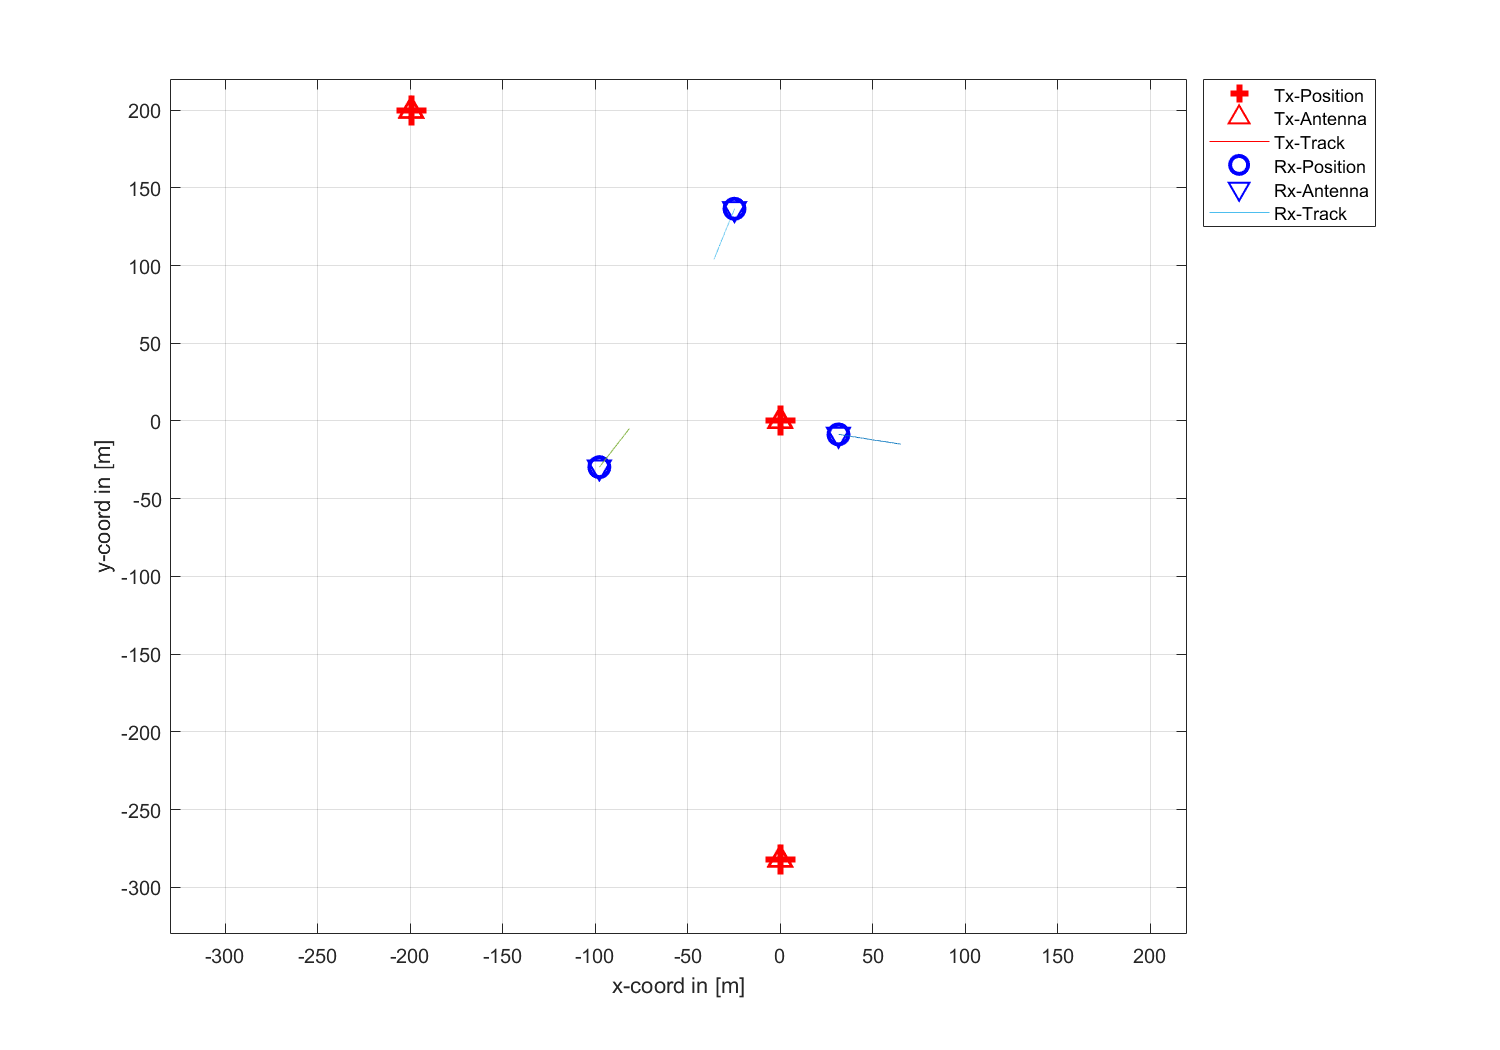

Index in position 1 exceeds array bounds.
Error in Write_Spectral_Tracks (line 98)
                        X = X(range_of_interest, :);
Error in mvrcQv2_MRO (line 36)
Write_Spectral_Tracks;

mvrcQv2_MRO;

c1 = c(1, 1, 1);
size(c1.coeff)

ans =            1          64          61        2000


size(c1.delay)

ans =            1          64          61        2000


size(c1.par.AoA_cb)

ans =      1    61


size(c1.par.AoD_cb)

ans =      1    61


size(c1.par.EoA_cb)

ans =      1    61


size(c1.par.EoD_cb)

ans =      1    61


## Wideband RSRP

useful_fft_points = 600;

WidebandRSRP;
rsrp_p0(:, :, 1) % each sectors results, time instance 1

ans =  -109.9102  -88.6778  -86.4080 -132.2530 -109.9354 -108.8572
  -90.0399 -113.6323 -105.6366  -76.6166 -102.4481  -93.1246
 -101.7481 -116.2007  -89.6885 -115.8667 -104.1408  -88.8181


Y_save = zeros(size(rsrp_p0));

## PSD RSRP

BW = 10;

BW_options   = [1.25, 2.5, 5, 10, 15, 20]; % requested bandwidth should be one of these
FFT_Sampling = [1.92, 3.84, 7.68, 15.36, 23.04, 30.72]*10e6;
FFT_options  = [128, 256, 512, 1024, 1536, 2048, ];
RB_options   = [6, 12, 25, 50, 75, 100];
SC_options   = 12 * RB_options;


choice = find(BW_options == BW);
if isempty(choice)
    choice = find(BW_options*10e6 == BW);
    if isempty(choice)
        error("No valid BW selected, try again");
    end
else
    BW = 10e6*BW;
end

num_RBs = RB_options(choice);
fft_size = FFT_options(choice);
fft_freq = FFT_Sampling(choice);
RB_BW = 180e3;
subcarrier_spacing_Hz = 15e3;


Tx_P = 10.^(0.1 * params.tx_pwr_dBm);

for rx_k = 1:l.no_rx
    for tx_k = 1:l.no_tx
        if ~params.batch
            for sector = 1:params.no_sectors
                % Get the frequency response values
                tx_sec_index = (tx_k-1)*params.no_sectors+sector;
                X = c(rx_k, tx_sec_index).fr(fft_freq, fft_size);
                X = squeeze(X);

                X = X(range_of_interest, :);
                % X = 10*log10(abs(X).^2./(fft_size*BW)); % normalization
                % already occurs in the .fr() method. Scale by transmit power
                X = abs(X).^2./(fft_size) .* pwr_mW_perSC_perMIMOtx;
                edges = 1:useful_fft_points / num_RBs:useful_fft_points + 1;
                bin_sets = discretize(1:useful_fft_points, edges);
                [~, len] = size(X);

                for i = 1:num_RBs
                    Y = mean(X(bin_sets == i, :), 1); % average over the bin
                    Y_save(rx_k, tx_sec_index, sector) = mean(X(bin_sets == i, :), 1);
                end

            Y_save = round(Y_save, 5, 'significant');
            end
            for sector = 1:params.no_sectors
                name = strcat(params.save_folder_r, 'ULDL_', 'TX_', num2str(tx_k), '_Sector_', num2str(sector), '_UE_', num2str(rx_k), '_Channel_Response');
                writematrix(Y_save(:, :, sector), strcat(name, '.csv'));

            end
        end
    end 
end

ans =  -104.1900  -84.1200  -82.3820 -132.1600 -108.5600 -109.2700
  -89.4630 -113.9600 -103.0700  -77.3350 -103.4800  -92.2420
 -103.4900 -116.5500  -89.6610 -115.2700 -104.8900  -87.5230


## Difference

Z = Y - rsrp_p0;
Z(:, :, 1)

ans =     5.7202    4.5578    4.0260    0.0930    1.3754   -0.4128
    0.5769   -0.3277    2.5666   -0.7184   -1.0319    0.8826
   -1.7419   -0.3493    0.0275    0.5967   -0.7492    1.2951


mean_z = mean(Z, 'all')

mean_z = 0.1834